%x = [x_pos; y_pos; z_pos; u; v; w; alpha; phi; theta; psi; p; q; r];

**Parachute parameters**

M_para = 5; %mass of the parachute
g = 9.81; %gravitational acceleration
I_x = 1; I_y = 1; I_z = 3; %Inertia matrix diagonal principal of the parachute 
CD_p = 0.9; %coefficient of drag of parachute
CL_p = 0; %coefficient of lift of parachute
rho = 1; %density of the atmosphere
x_com = 0; y_com = 0; z_com = -5; %position of COM of the paarchute from the integrated system's COM(body axis origin)
A = 10; %parachute area


**Vehicle parameters**

M_vehicle = 0; %mass of the vehicle
I_v = 0 ;%Inertia matrix of vehicle
CD_v = 0 ; %drag coeff of vehicle
CL_v = 0 ;%lift coeff of vehicle

**Fucntion definition**

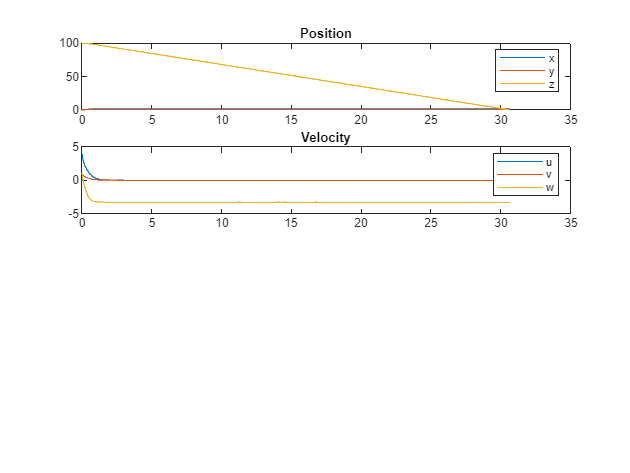

%% 6DOF fucntion definition
function [dxdt, aoa_series] = six_DOF_dynamics(t,x)


M_para = 5; %mass of the parachute in Kgs
g = 9.81; %gravitational acceleration in m/s^2
I_x = 1; I_y = 1; I_z = 3; %Inertia matrix diagonal principal of the parachute in kg-m^2
CD_para = 0.9; %coefficient of drag of parachute
CL_para = 0; %coefficient of lift of parachute
rho = 1; %density of the atmosphere in Kg/m^3
x_para_com = 0; y_para_com = 0; z_para_com = -5; %position of COM of the paarchute from the integrated system's COM(body axis origin) in m
A = 10; %parachute area in m^2
x_system_com = 0; y_system_com = 0; z_system_com = 0;

%L_para_com_to_system_com = ((x_system_com - x_para_com)^2 + (y_system_com - y_para_com)^2 + (z_system_com - z_para_com)^2)^0.5;


    %state variables defining
    x_pos = x(1); y_pos = x(2); z_pos = x(3); %postion variables
    u = x(4); v = x(5); w = x(6); %velocity variables 
    % phi = x(7); theta = x(8); psi = x(9); %attitude/euler angles variables
    % p = x(10); q = x(11); r = x(12); %euler angular rate variables
    
   v_para_x = u;
   v_para_y = v;
   v_para_z = w;

    %rate of change of postion -> velocity
    % dx_pos = u*cos(theta)*cos(psi) + v*(sin(phi)*sin(theta)*cos(psi) - cos(phi)*sin(psi)) + w*(sin(phi)*sin(psi) + cos(phi)*sin(theta)*cos(psi));
    % dy_pos = u*cos(theta)*sin(psi) + v*(sin(phi)*sin(theta)*sin(psi) + cos(phi)*cos(psi)) + w*(-sin(phi)*sin(psi) + cos(phi)*sin(theta)*sin(psi));
    % dz_pos = u*sin(theta) - v*cos(theta)*sin(phi) - w*cos(phi)*cos(theta);

    dx_pos = u;
    dy_pos = v;
    dz_pos = w;

    %Gravity moment of the parachute along x,y and z components
    % GravityMoment_para_x = M_para*g*cos(theta)*(y_para_com*cos(phi) - z_para_com*sin(phi));
    % GravityMoment_para_y = M_para*g*(z_para_com*sin(theta) - x_para_com*cos(theta)*cos(phi));
    % GravityMoment_para_z = M_para*g*(x_para_com*cos(theta)*sin(phi) + y_para_com*sin(theta));

    v_para_total = sqrt(v_para_x^2 + v_para_y^2 + v_para_z^2); %net speed
    
    persistent angle_of_attack %defining this variable to take it as a output outside ode45

    alpha = acos(v_para_z/v_para_total); %angle of attack calculated in radians

    angle_of_attack = [angle_of_attack; alpha]; %concatinating current iterated angle of attack in global variable

    %Componetize CD and CL into tangential and normal force coefficients
    CT = CD_para*cos(alpha) - CL_para*sin(alpha);
    CN = CL_para*cos(alpha) + CD_para*sin(alpha);

    % Aerodynamic force along x,y,z axes F = 0.5*rho*v^2*A
    if (u == 0 & v == 0) 
        Aerodynamic_force_x = 0;
        Aerodynamic_force_y = 0;
        Aerodynamic_force_z = -0.5*rho*CT*v_para_total*v_para_total*A;
    else 
        Aerodynamic_force_x = -0.5*rho*CN*v_para_total*v_para_total*A*(v_para_x/(v_para_x^2 + v_para_y^2)^0.5); 
        Aerodynamic_force_y = -0.5*rho*CN*v_para_total*v_para_total*A*(v_para_y/(v_para_x^2 + v_para_y^2)^0.5);
        Aerodynamic_force_z = -0.5*rho*CT*v_para_total*v_para_total*A;
    end

 
    %Moment caused by aerodynamic force along x,y,x
    % Aerodynamic_moment_x = y_para_com*Aerodynamic_force_z - z_para_com*Aerodynamic_force_y;
    % Aerodynamic_moment_y = z_para_com*Aerodynamic_force_x - x_para_com*Aerodynamic_force_z;
    % Aerodynamic_moment_z = x_para_com*Aerodynamic_force_y - y_para_com*Aerodynamic_force_x;

    %rate change of velocity definition
    % du = v*r - w*q + g*sin(theta) + Aerodynamic_force_x/M_para;
    % dv = -u*r + w*p + g*cos(theta)*sin(phi) + Aerodynamic_force_y/M_para;
    % dw = u*q - v*p + g*cos(theta)*cos(phi) + Aerodynamic_force_z/M_para;

    %rate change of velocity definition
    du = Aerodynamic_force_x/M_para;
    dv = Aerodynamic_force_y/M_para;
    dw = -g + Aerodynamic_force_z/M_para;

    %rate change of euler angles definition
    % dphi = p + (r*cos(phi) + q*sin(phi))*tan(theta);
    % dtheta = q*cos(phi) - r*sin(phi);
    % dpsi = (cos(theta)^-1)*(r*cos(phi) + q*sin(phi));

    %rate change of angular rates definition
    % dp = (1/I_x)*(Aerodynamic_moment_x + GravityMoment_para_x);
    % dq = (1/I_y)*(Aerodynamic_moment_y + GravityMoment_para_y);
    % dr = (1/I_z)*(Aerodynamic_moment_z + GravityMoment_para_z);

    %dxdt = [dx_pos; dy_pos; dz_pos; du; dv; dw; dphi; dtheta; dpsi; dp; dq; dr];

    dxdt = [dx_pos; dy_pos; dz_pos; du; dv; dw];

    %block to output angle of attack
    if nargout>1
        aoa_series = angle_of_attack;

    end
      
end

tspan = [0 50];

%x0 = [0; 0; 100; 0; 1; 1; 0; 0; 0; 0; 0; 0];

x0 = [0; 0; 100; 4; 1; 1];

Option = odeset('Events',@Zero_height_event);

[t, x] = ode45(@six_DOF_dynamics, tspan, x0, Option);

function [value, isterminal, direction] = Zero_height_event(t,x) 
    value = (x(3) <= 0);
    isterminal = 1;
    direction = 0;

end

[~, aoa_series] = six_DOF_dynamics(t,x);

%adding alpha as a part of x


% Plot results
figure;
subplot(4,1,1);
plot(t, x(:,1:3));
title('Position');
legend('x', 'y', 'z');

subplot(4,1,2);
plot(t, x(:,4:6));
title('Velocity');
legend('u', 'v', 'w');

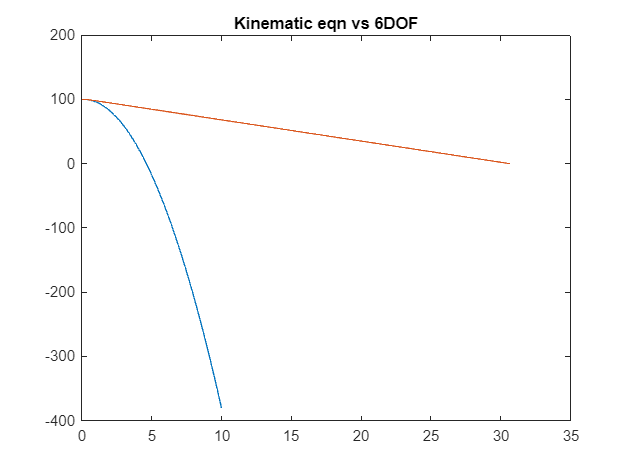


% subplot(4,1,3);
% plot(t, x(:,7:9));
% title('Euler Angles');
% legend('phi', 'theta', 'psi');
% 
% subplot(4,1,4);
% plot(t, x(:,10:12));
% title('Euler Rates');
% legend('p', 'q', 'r');

figure 
t_kin = 0:0.1:10;
plot(t_kin, 100 + t_kin.*1 - 0.5*9.81*t_kin.^2)
title('Kinematic eqn vs 6DOF');
hold on;
plot(t,x(:,3));
hold off;

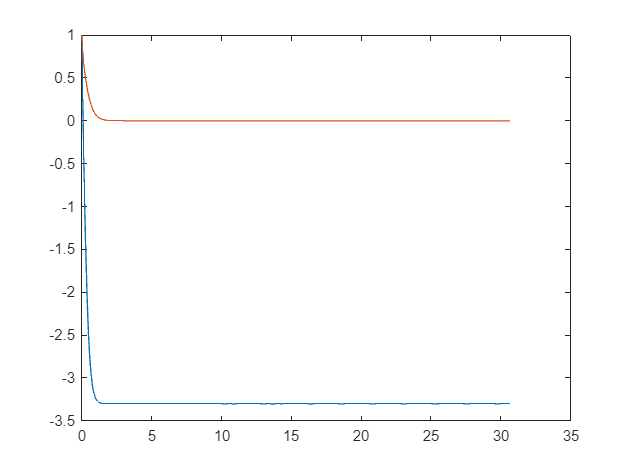


figure 
plot(t,x(:,6)); hold on;
plot(t,x(:,5)); hold off;